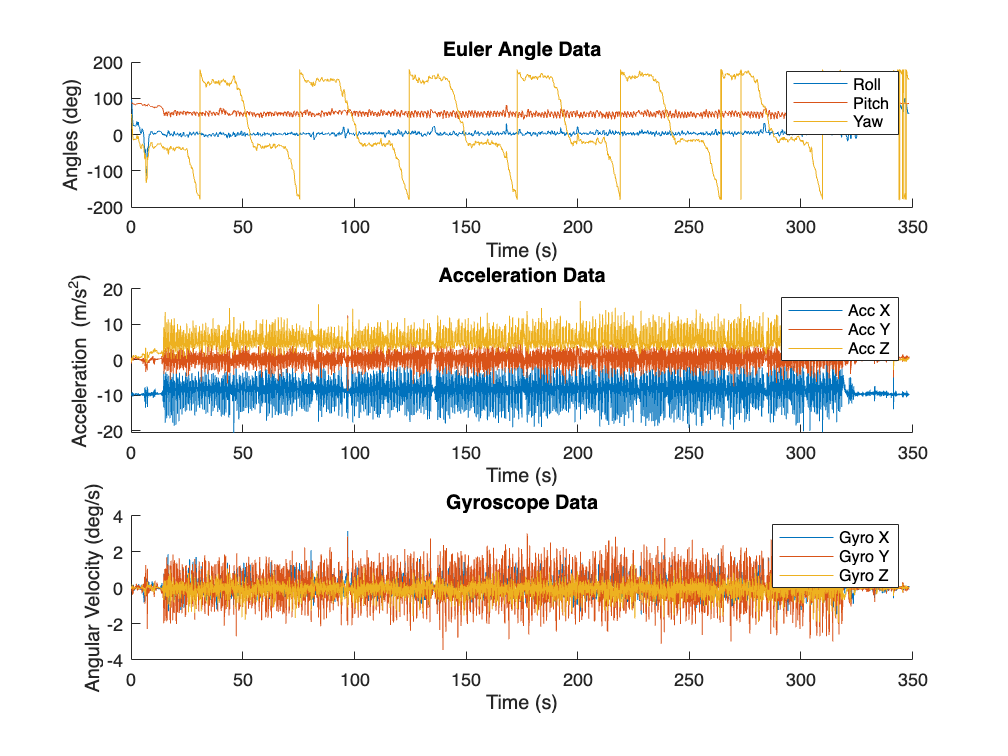

fileName = 'test2.BIN';

dataRaw = data_processing_bin(fileName);

data = label_data(dataRaw);

figure(); hold on;
% Plotting Roll, Pitch, Yaw
ax1 = subplot(3,1,1); hold on;
plot(data.Time, data.IMUroll, 'DisplayName', 'Roll');
plot(data.Time, data.IMUpitch, 'DisplayName', 'Pitch');
plot(data.Time, data.IMUyaw, 'DisplayName', 'Yaw');
title('Euler Angle Data');
xlabel('Time (s)');
ylabel('Angles (deg)');
legend;

% Plotting Acceleration data
ax2 = subplot(3,1,2); hold on;
plot(data.Time, data.IMUaccX, 'DisplayName', 'Acc X');
plot(data.Time, data.IMUaccY, 'DisplayName', 'Acc Y');
plot(data.Time, data.IMUaccZ, 'DisplayName', 'Acc Z');
title('Acceleration Data');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
legend;


% Plotting Gyroscope data
ax3 = subplot(3,1,3); hold on;
plot(data.Time, data.IMUgyroX, 'DisplayName', 'Gyro X');
plot(data.Time, data.IMUgyroY, 'DisplayName', 'Gyro Y');
plot(data.Time, data.IMUgyroZ, 'DisplayName', 'Gyro Z');
title('Gyroscope Data');
xlabel('Time (s)');
ylabel('Angular Velocity (deg/s)');
legend;

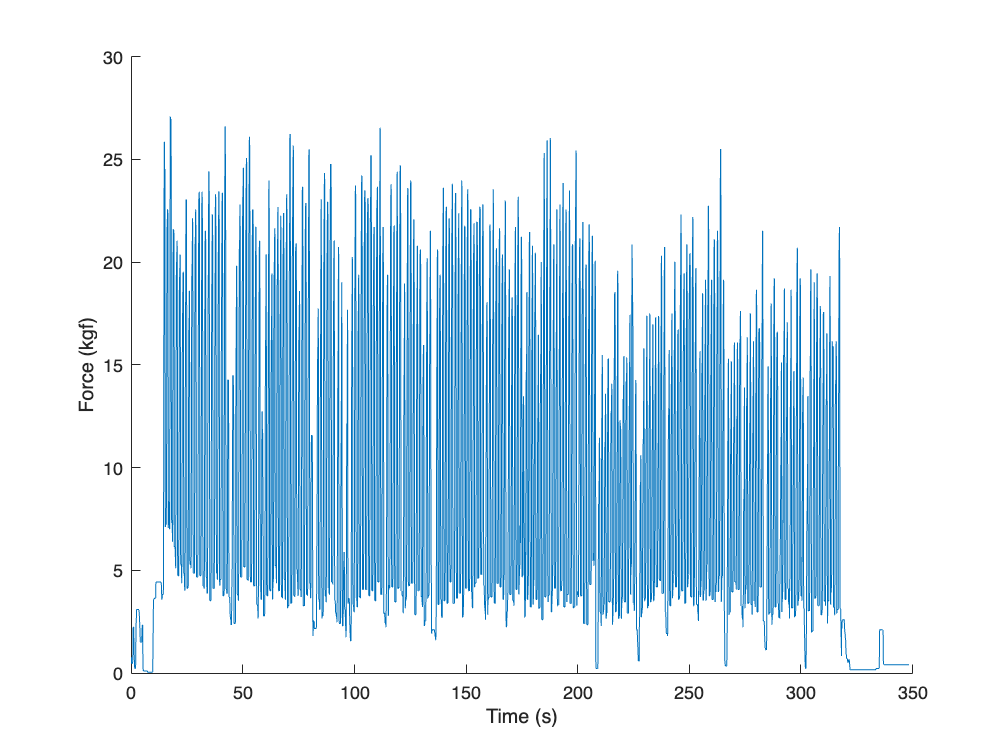


if exist('time_range', 'var')
    set([ax1, ax2, ax3], 'XLim', time_range);    
end

figure(); hold on;
plot(data.Time, data.forceMeasured);
xlabel('Time (s)');
ylabel('Force (kgf)');